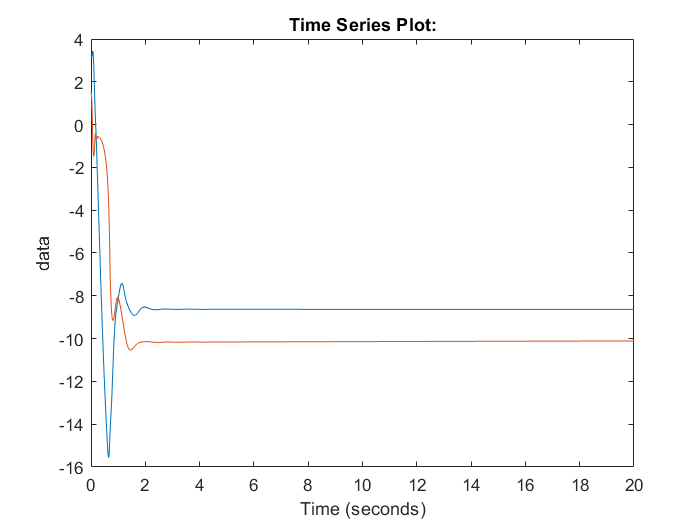

% Double Pendulum trajectory

M = readmatrix('DoublePendulumSwing.csv');
u1input = M(2:end,2);
u2input = M(2:end,3);
tau1 = M(2:end,8);
tau2 = M(2:end,9);

position = [];
for i = 1:length(u1input)
    u1 = u1input(i);
    u2 = u2input(1);
    sim('test_4_5.slx');
    position = ans.position_data;
end

plot(position)